# Scale-invariant Feature Transforma (SIFT) - Part 1

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2018-11-20

- Concept of Descriptor

- Scale space

### Laplacian of Gaussian (Filter Size)

clear; close all; clc;

x= -10:0.01:10;
sigma = 1;
g = 1/(sigma*sqrt(2*pi))*exp(-1/2*((x)/sigma).^2);

% https://en.wikipedia.org/wiki/68%E2%80%9395%E2%80%9399.7_rule

fig1 = figure(1);
set(fig1,'Position', [100 100 800 250]);

subplot(131); plot(x, g, 'b', 'linewidth', 2); hold on;
errorbar(0, 0, 3*sigma, 'horizontal', 'linewidth', 2, 'color', 'r');
text(0, 0,'\bf 6\sigma','fontSize', 8, 'HorizontalAlignment', 'center', 'VerticalAlignment','top')
grid on; hold off;
xlabel('\bf x-axis'); 
ylabel('\bf g(x)'); ylim([-0.05 max(g)])
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold');

gpp = -1/(sigma*sqrt(2*pi)*sigma^3)*(1-x.^2/sigma^2).*exp(-1/2*((x)/sigma).^2);

subplot(132); plot(x, gpp, 'b', 'linewidth', 2); hold on;
errorbar(0, 0, 3*sigma, 'horizontal', 'linewidth', 2, 'color', 'r');
text(3*sigma, -0.02,'\bf 6 \sigma ','fontSize', 8, 'HorizontalAlignment', 'center', 'VerticalAlignment','top')
grid on; hold off;
xlabel('\bf x-axis'); 
ylabel('\bf g''''(x)'); ylim([min(gpp) 0.3])
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold');

subplot(133); plot(x, gpp, 'b', 'linewidth', 2); hold on;
errorbar(0, 0, 3*sqrt(2)*sigma, 'horizontal', 'linewidth', 2, 'color', 'r');
% https://en.wikipedia.org/wiki/68%E2%80%9395%E2%80%9399.7_rule
text(3*sqrt(2)*sigma, -0.02,'\bf 6(2)^{(1/2)} \sigma ','fontSize', 8, 'HorizontalAlignment', 'center', 'VerticalAlignment','top')
grid on; hold off;
xlabel('\bf x-axis'); 
ylabel('\bf g''''(x)'); ylim([min(gpp) 0.3])
set(gca,'fontsize',10,'linewidth',2,'fontweight','bold');

log_filter = fspecial('log', 13, sqrt(2));


### Separable Filter

[http://www.songho.ca/dsp/convolution/convolution2d_separable.html](http://www.songho.ca/dsp/convolution/convolution2d_separable.html) 

% http://watkins.cs.queensu.ca/~jstewart/457/notes/10-separable-filters-notes.html

gx = fspecial('gaussian',[21 1],sqrt(2));
gy = fspecial('gaussian',[21 1],sqrt(2));
Gxy = fspecial('gaussian',[21 21],sqrt(2));
img = imread('sunflower-832793_1920_gray.jpg');

tic;
img_c1 = conv2(conv2(img, gx,'same'), gy,'same');
time1 = toc;

tic;
img_c2 = conv2(img, Gxy,'same');
time2 = toc;

figure(1)
subplot(121);imshow(img_c1./max(img_c1(:)));
subplot(122);imshow(img_c2./max(img_c2(:)));


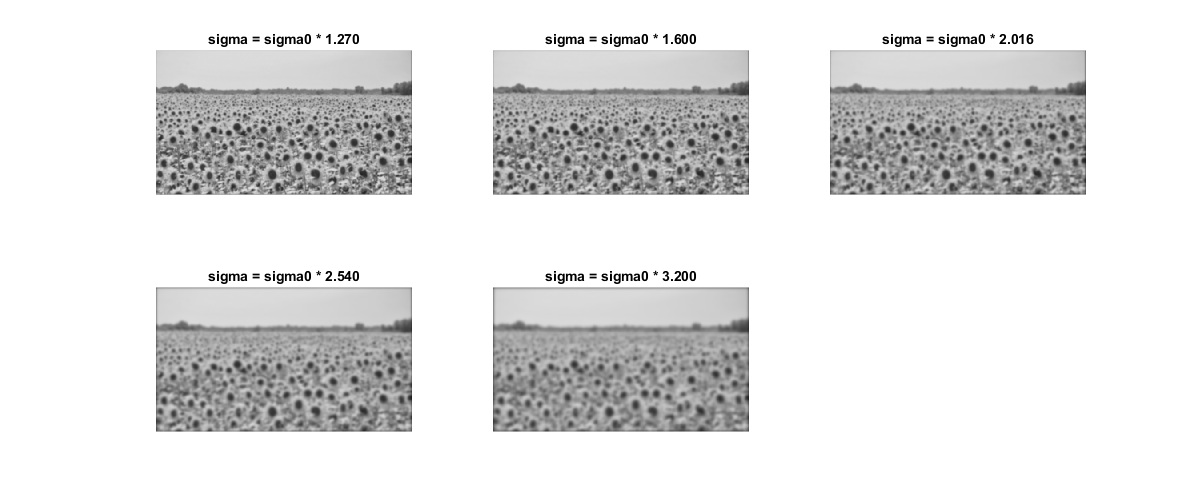

% https://pixabay.com/en/sunflower-yellow-flower-832793/
img = imread('sunflower-832793_1920_gray.jpg');
img = im2double(img);
img = imresize(img,0.3);

sigma0 = 1.6;
s = 3;
octave = 3;

sigma = sigma0 * 2.^((-1:s+1)/s);
filters = cell(numel(sigma),1);
for ii=1:numel(sigma)
    filters{ii} = fspecial('gaussian', round(6*sigma(ii)),sigma(ii));
end

% first octave
img1 = img;

img_g = zeros(size(img1,1), size(img1, 2), numel(sigma));
for ii=1:numel(sigma)
    img_g(:,:,ii) = conv2(img1, filters{ii}, 'same');
end

img_dog = zeros(size(img1,1), size(img1, 2), numel(sigma)-1);
for ii=1:(s+1)
    img_dog(:,:,ii) = img_g(:,:,ii+1)-img_g(:,:,ii);
end

dog_maxima = zeros(size(img1,1), size(img1, 2), s);
for ii=1:s
    tmp = imregionalmax(img_dog(:,:,(ii:ii+2)), 26);
    dog_maxima(:,:,ii) = tmp(:,:,2);
end

fig1 = figure(1);
set(fig1,'Position', [100 100 1200 500]);
for ii=1:(s+2)
    subplot(2,3,ii); imshow(img_g(:,:,ii)); 
    title(sprintf('sigma = sigma0 * %2.3f', sigma(ii)));    
end

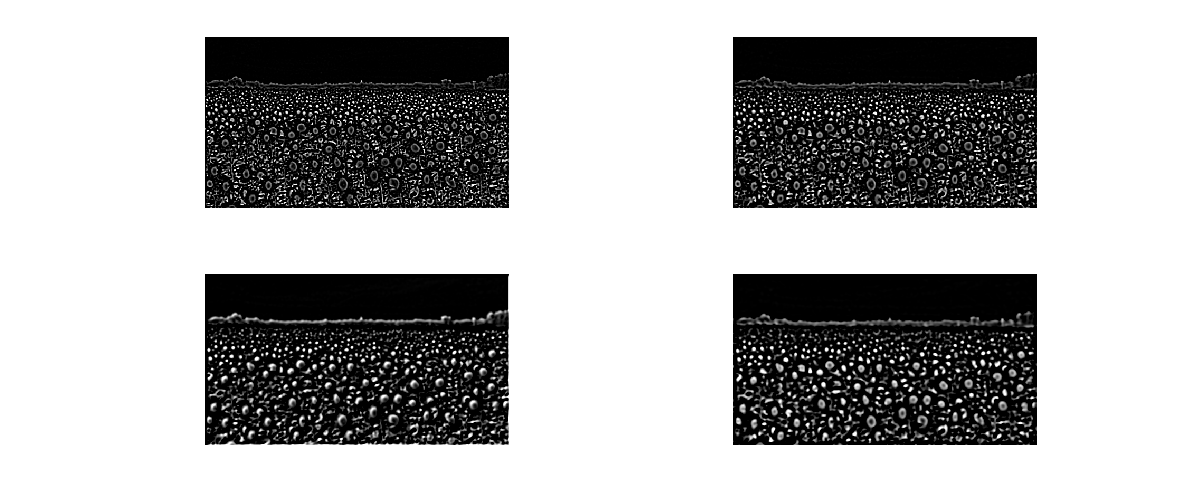


fig2 = figure(2);
set(fig2,'Position', [100 100 1200 500]);
for ii=1:(s+1)
    subplot(2,2,ii); imshow(imadjust(img_dog(:,:,ii))); 
end


% second octave
img2 = img_g(1:2:end,1:2:end,end);

img_g = zeros(size(img2,1), size(img2, 2), numel(sigma));
for ii=1:numel(sigma)
    img_g(:,:,ii) = conv2(img2, filters{ii}, 'same');
end

img_dog = zeros(size(img2,1), size(img2, 2), numel(sigma)-1);
for ii=1:(s+1)
    img_dog(:,:,ii) = img_g(:,:,ii+1)-img_g(:,:,ii);
end

dog_maxima = zeros(size(img2,1), size(img2, 2), s);
for ii=1:s
    tmp = imregionalmax(img_dog(:,:,(ii:ii+2)), 26);
    dog_maxima(:,:,ii) = tmp(:,:,2);
end

fig1 = figure(4);
set(fig1,'Position', [100 100 1200 500]);
for ii=1:(s+2)
    subplot(2,3,ii); imshow(img_g(:,:,ii)); 
    title(sprintf('sigma = sigma0 * %2.3f', sigma(ii)));    
end

fig2 = figure(5);
set(fig2,'Position', [100 100 1200 500]);
for ii=1:(s+1)
    subplot(2,2,ii); imshow(imadjust(img_dog(:,:,ii))); 
end

% third octave
img3 = img_g(1:2:end,1:2:end,end);

img_g = zeros(size(img3,1), size(img3, 2), numel(sigma));
for ii=1:numel(sigma)
    img_g(:,:,ii) = conv2(img3, filters{ii}, 'same');
end

img_dog = zeros(size(img3,1), size(img3, 2), numel(sigma)-1);
for ii=1:(s+1)
    img_dog(:,:,ii) = img_g(:,:,ii+1)-img_g(:,:,ii);
end

fig1 = figure(6);
set(fig1,'Position', [100 100 1200 500]);
for ii=1:(s+2)
    subplot(2,3,ii); imshow(img_g(:,:,ii)); 
    title(sprintf('sigma = sigma0 * %2.3f', sigma(ii)));    
end

fig2 = figure(7);
set(fig2,'Position', [100 100 1200 500]);
for ii=1:(s+1)
    subplot(2,2,ii); imshow(imadjust(img_dog(:,:,ii))); 
end